syms r; 
syms k;
syms k0;
syms b1;
syms b2;
syms b0;
syms I1;
syms I2;
syms I3;
syms u1;
syms u2;
syms I2;
syms m;
syms theta_1;
syms theta_2;
syms x;


syms theta_dot_1;
syms theta_dot_2;
syms x_dot;

syms theta_ddot_1;
syms theta_ddot_2;
syms x_ddot;



b = 0.09;
I = 0.0008;
I1 = I;
I2 = I;
m = 0.35;
r = 0.03;
k = 50;
k0 = 200;
b = 0.09;
b1 = b;
b2 = b;
b0 = 0.5;
%let cos(alpha) = a
a = sqrt(3)/2;
G = 300; %amplifier/motor voltage to torque gain.
y = 0.4; 



s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



Gw = 1/(2*(I*s+b))

Gw =
 
         1
  ---------------
  0.0016 s + 0.18
 
Continuous-time transfer function.



Gx = (sqrt(3)*k*r)/((I*s^2 + 3*k*r^2)*(2*m*s^2 + 2*k0 +3*k)-3*k^2*r^2)

Gx =
 
               2.598
  -------------------------------
  0.00056 s^4 + 0.5345 s^2 + 67.5
 
Continuous-time transfer function.




P=[Gw Gw;
    -Gx Gx]

P =
 
  From input 1 to output...
              1
   1:  ---------------
       0.0016 s + 0.18
 
                   -2.598
   2:  -------------------------------
       0.00056 s^4 + 0.5345 s^2 + 67.5
 
  From input 2 to output...
              1
   1:  ---------------
       0.0016 s + 0.18
 
                    2.598
   2:  -------------------------------
       0.00056 s^4 + 0.5345 s^2 + 67.5
 
Continuous-time transfer function.



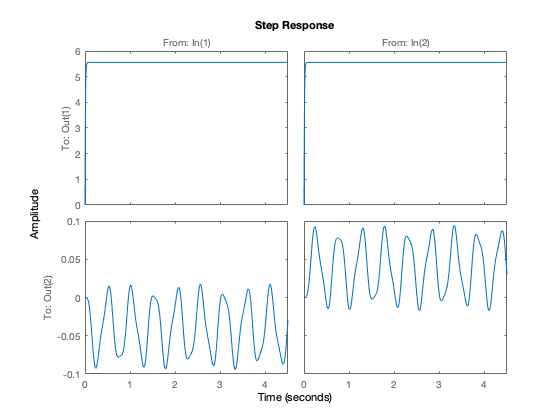


step(P)


alpha = 1/(0.3*s+1)

alpha =
 
      1
  ---------
  0.3 s + 1
 
Continuous-time transfer function.



beta = -185600/((s^2+11*s+150)*(s^2+1.6*s+800))

beta =
 
                    -185600
  --------------------------------------------
  s^4 + 12.6 s^3 + 967.6 s^2 + 9040 s + 120000
 
Continuous-time transfer function.



newthing = [alpha 0; 0 beta]

newthing =
 
  From input 1 to output...
           1
   1:  ---------
       0.3 s + 1
 
   2:  0
 
  From input 2 to output...
   1:  0
 
                         -185600
   2:  --------------------------------------------
       s^4 + 12.6 s^3 + 967.6 s^2 + 9040 s + 120000
 
Continuous-time transfer function.



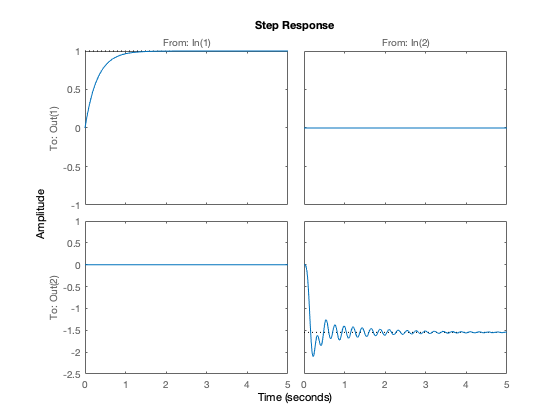


step(newthing)


system = ss(newthing)

system =
 
  A = 
           x1      x2      x3      x4      x5
   x1  -3.333       0       0       0       0
   x2       0   -12.6  -30.24  -17.66  -14.65
   x3       0      32       0       0       0
   x4       0       0      16       0       0
   x5       0       0       0      16       0
 
  B = 
       u1  u2
   x1   2   0
   x2   0   4
   x3   0   0
   x4   0   0
   x5   0   0
 
  C = 
           x1      x2      x3      x4      x5
   y1   1.667       0       0       0       0
   y2       0       0       0       0  -5.664
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.

